# Validate ODE Response

clear;clc;

dt = 0.01;
T = 10;
t = 0:dt:T-dt;

s = tf('s');
sysa = 1/(s^2+3*s+2);
sysb = 1/(s^2+2*s+2);

## Simulate a(i)

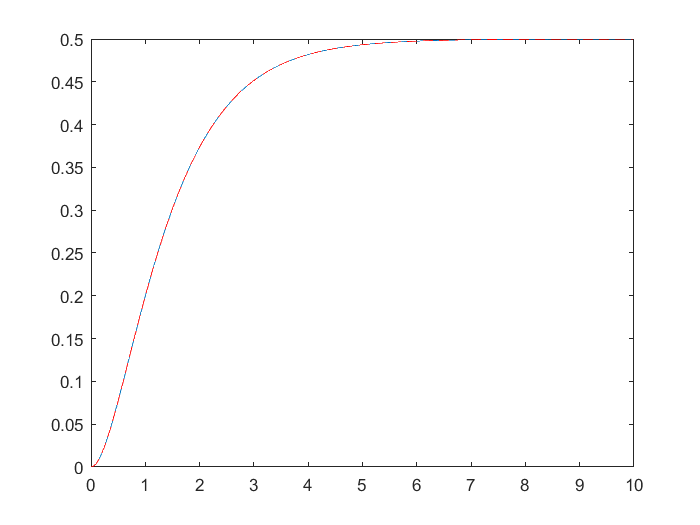

ysim = step(sysa,t);
figure(1);
plot(t,ysim);
hold on;
yana = 0.5-exp(-t)+0.5*exp(-2*t);
plot(t,yana,'r--');

## Simulate a(ii)

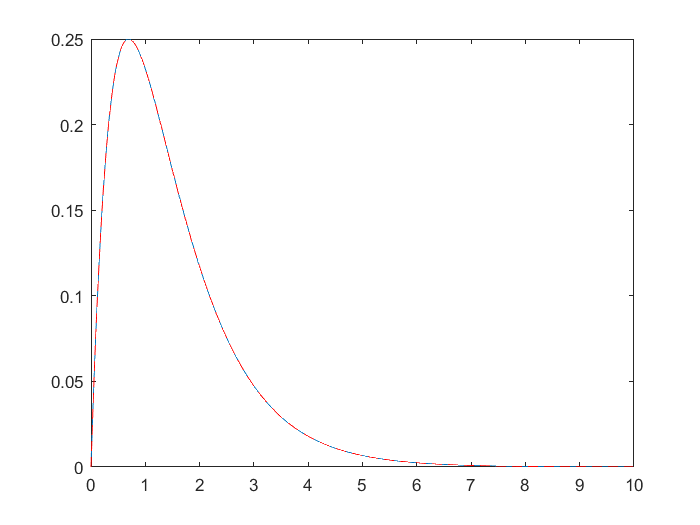

ysim = impulse(sysa,t);
figure(2);
plot(t,ysim);
hold on;
yana = exp(-t)-exp(-2*t);
plot(t,yana,'r--');

## Simulate b(i)

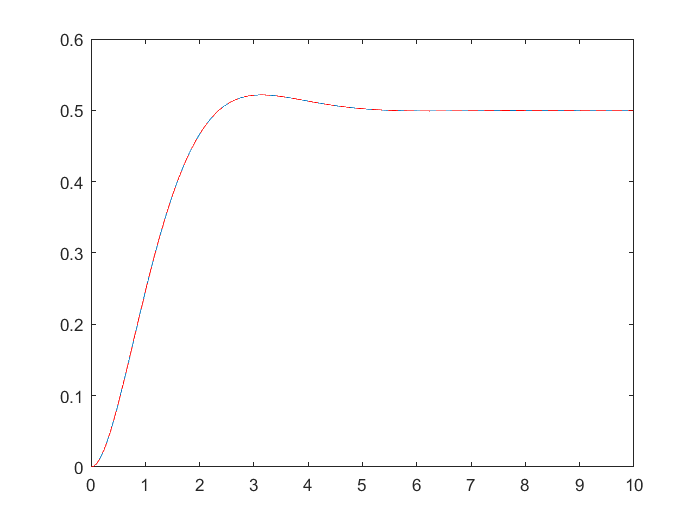

ysim = step(sysb,t);
figure(3);
plot(t,ysim);
hold on;
yana = 0.5*(1-exp(-t).*(cos(t)+sin(t)));
plot(t,yana,'r--');

## Simulate b(ii)

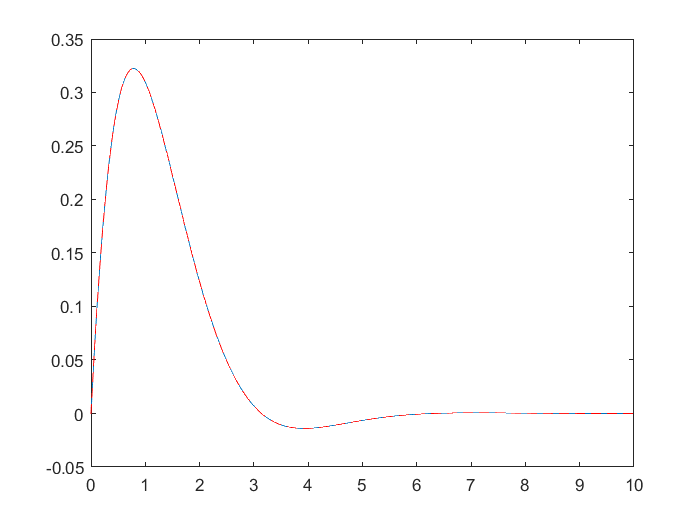

ysim = impulse(sysb,t);
figure(4);
plot(t,ysim);
hold on;
yana = exp(-t).*sin(t);
plot(t,yana,'r--');